%get data
load fisheriris.mat
%create vectors for classification
X = meas(:,3:4); %get rows 3 and 4

[N,~] = size(X);%use ~ to ommit the second returned parameter

x = ones(3,N); %1st row is filled with ones
x(2,:) = transpose(X(:,1)); %feature 1
x(3,:) = transpose(X(:,2)); %feature 2

y = ones(1,N); %learning data

figure(1); hold on %create figure

for i=1:N
    if strcmp(species{i,1} , 'setosa')
        mc = 'b*';
        y(i) = 0; %distinguish this specie
    end
    if strcmp(species{i,1} , 'virginica')
        mc = 'g*';
    end
    if strcmp(species{i,1} , 'versicolor')
        mc = 'r*';
        
    end
    plot(x(2,i),x(3,i),mc,'MarkerSize',3); %plot a data point
end
title 'Fisher''s Iris Data';
xlabel 'Petal Lengths (cm)'; 
ylabel 'Petal Widths (cm)';

%name the groups
text(6,1.5,'virginica');
text(4.3,1,'versicolor');
text(2.3,0.25,'setosa');

h = @(th,x)(1./(1 + exp(-th'*x))); %logistic function
C = @(th,x)(h(th,x) >= 0.5);%classification function

corr = 1e-8;

f = @(th)(-1/N*( y* (log(h(th,x) + corr))' + (1 - y)*(log(1 - h(th,x) + corr))')); %objective function

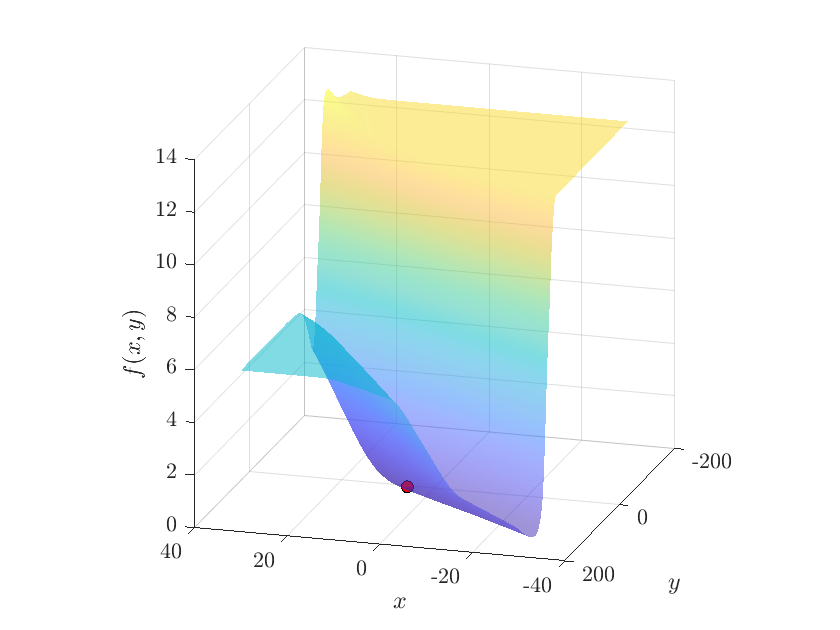

% set axes
x1 = [-30:1:30]; m = length(x1);
y1 = [-200:1:200]; n = length(y1);
F = zeros(n,m);
% create meshgrid
[xx, yy] = meshgrid(x1,y1);

th0 = [1,1,1]';

tol = 1e-3;
k = 1;
thS = th0;

%Gradient

%{
curEval = df(thS);
sigma = 1;
while (sum(curEval.^2) ^ (1/2) > tol && k < 10000)
    thS = thS - sigma * curEval;
    curEval = df(thS);
    k = k + 1;
end
%}


% Newton
curEval = df(thS, x, h, y);
curH = Hessian(thS, x, h);
sigma = 1.2;
while (sum(curEval.^2) ^ (1/2) > tol && k < 1000)
    thS = thS - sigma .* curH^-1 * curEval;
    curEval = df(thS, x, h, y);
    curH = Hessian(thS, x, h);
    k = k + 1;
end


% ***************************************

%thS = [45, -5.7, -10.4]'; %pre-set "optimal" point

% get function shape on theta(1) level
for i = 1:n
    for j = 1:m
        F(i,j) = f([thS(1), xx(i,j), yy(i,j)]');
    end
end

% plot
figure;
hold on

view([-20,30]);
surf(xx, yy, F,'FaceAlpha',0.5,'EdgeColor','none','FaceColor','interp','AmbientStrength',0.3);
zlabel('$f(x,y)$','interpreter','latex','FontSize',13);
grid;

axis square %make axis one-scale
xlabel('$x$','interpreter','latex','FontSize',13);
ylabel('$y$','interpreter','latex','FontSize',13);
set(1,'position',[100 30 660 600]);
set(gca,'TickLabelInterpreter','latex','FontSize',11);

%draw thS as a marker
scatter3(thS(2),thS(3),f(thS),'MarkerFaceColor','red','MarkerEdgeColor','black');

view([-163.5 17.7])

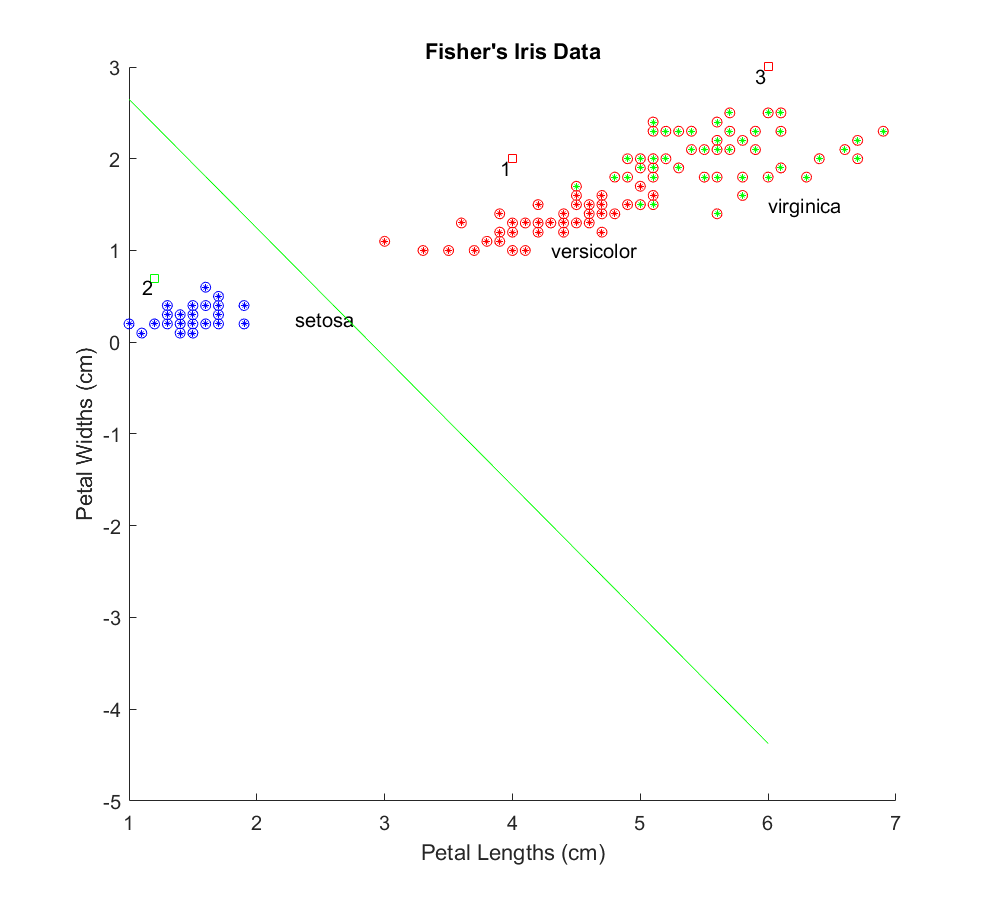


%return to figure 1
figure(1);
for i = 1:N
     if C(thS,x(:,i)) > 0 %classify 
        plot(x(2,i),x(3,i),'ro','MarkerSize',5);
     else
        plot(x(2,i),x(3,i),'bo','MarkerSize',5);
     end
end
%draw line
if thS(3) ~= 0
    xspan = min(x(2,:)):max(x(2,:));
    yspan = (- thS(2)*xspan - thS(1))/thS(3);
else
    yspan = min(x(3,:)):max(x(3,:));
    xspan = -thS(1)/thS(2) + 0*yspan;
end
plot(xspan,yspan,'g-');

%synthetic irises
xS = [1, 1, 1;
      4, 1.2, 6;
      2, 0.7, 3];
for i = 1:3
  if C(thS,xS(:,i)) > 0 %classify
      plot(xS(2,i),xS(3,i),'rs','MarkerSize',5);
  else
      plot(xS(2,i),xS(3,i),'gs','MarkerSize',5);
  end
  text(xS(2,i) - 0.1,xS(3,i) - 0.1,num2str(i));%subscribe the point
end